# Mohammadreza Arani

## Convex Optimization

## 810100511

## Hw8 - Q6:

clear;
clc;
close all;
% Load Data:
run('rank_aggr_data.m');

cvx_begin
    variables r(n) v(m)
        minimize (sum(square_pos(v)));
        subject to
        v == r(preferences(:,2)) + 1 - r(preferences(:,1))
cvx_end

 
Calling SDPT3 4.0: 4050 variables, 2000 equality constraints
------------------------------------------------------------

 num. of constraints = 2000
 dim. of sdp    var  = 2000,   num. of sdp  blk  = 1000
 dim. of linear var  = 1000
 dim. of free   var  = 50 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|4.5e+01|4.5e+01|4.2e+06| 1.000000e+04  0.000000e+00| 0:0:00| spchol  1  1 
 1|0.291|0.290|3.2e+01|3.2e+01|2.5e+06| 4.103705e+04 -2.800853e+04| 0:0:00| spchol  1  1 
 2|0.300|0.288|2.2e+01|2.3e+01|2.1e+06| 7.521042e+04 -5.899901e+04| 0:0:00| spchol  1  1 
 3|0.427|0.367|1.3e+01|1.5e+01|


v_sq = pos(v);
num_viol_sq = sum(v_sq>0.001)

num_viol_sq = 781

## find rankings with sum of violations penalty:



cvx_begin
    variables r(n) v(m)
        minimize (sum(pos(v)));
        subject to
        v == r(preferences(:,2)) + 1 - r(preferences(:,1))
cvx_end

 
Calling SDPT3 4.0: 2050 variables, 1000 equality constraints
------------------------------------------------------------

 num. of constraints = 1000
 dim. of linear var  = 2000
 dim. of free   var  = 50 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.7e-01|6.8e+01|5.0e+06| 4.472136e+04  0.000000e+00| 0:0:00| spchol  1  1 
 1|1.000|0.985|1.2e-06|1.3e+00|1.2e+05| 4.315623e+04  2.792196e+02| 0:0:00| spchol  1  1 
 2|1.000|0.796|6.1e-07|3.4e-01|3.5e+04| 2.090350e+04  2.702304e+02| 0:0:00| spchol  1  1 
 3|0.950|0.927|1.7e-06|5.0e-02|4.6e+03| 4.006383e+03  2.464098e+02| 0:0:00| spchol  1  


v_lin = pos(v);
num_viol_lin = sum(v_lin>0.001)

num_viol_lin = 235

## plot Figures:

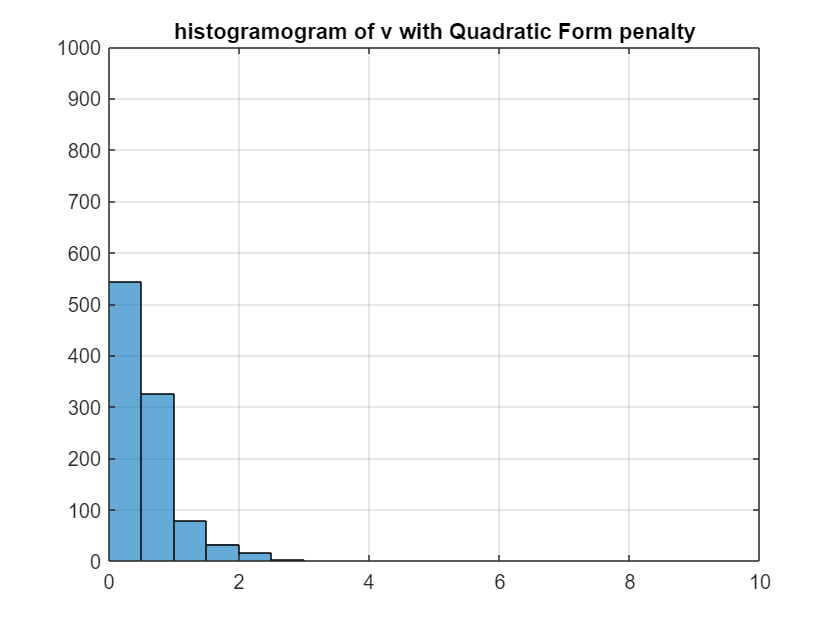


Fig1= figure();
histogram(v_sq,0:0.5:7.5);
title('histogramogram of v with Quadratic Form penalty');
grid on
xlim([0 10]);
ylim([0 1000]);

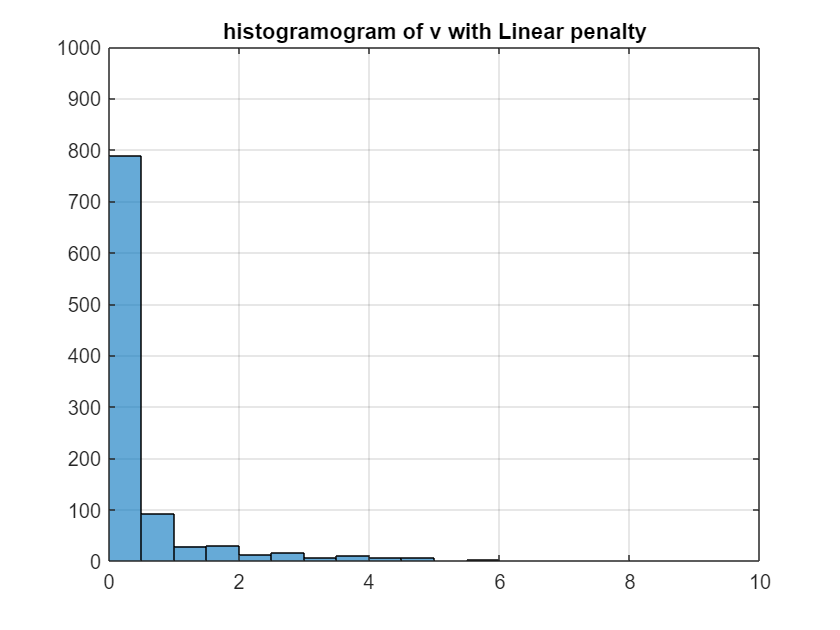


Fig2 = figure();
histogram(v_lin,0:0.5:7.5);
xlim([0 10]);
ylim([0 1000]);
title('histogramogram of v with Linear penalty');
grid on